# Non-Parametric ANOVA Example

Andrew Brown and Michael Rizzo

GEEN 3853: Data Analysis for Engineers

11/16/2020

## INTRODUCTION

This The following code analyzes the data for our Measure It project. The purpose is to determine any difference in protection between the 4 major types of UV-blocking glasses: Polarized, Non-Polarized, Blue Light, and UV400. Since the UV400 glasses are marketed as the best protection from UV you can buy, we expect them to have the most protection. 

The data for this experiment was taken using the Adafruit GUVA-S12SD Analog UV Light Sensor Breakout Board, a 365 nm UV light source, and a makeshift integrating sphere made out of a cardboard tube lined with tinfoil, which has been shown to reflect up to 85% of UV light. Data was taken using a National Instruments USB-6002 and LabView software. 

#### **Research Question**

To what extent do the 4 major UV-blocking glasses on the market protect your eyes from harmful UV light? 

How do each of the 4 major UV-blocking glasses on the market compare to each other in terms of UV protection?

## PREP WORKSPACE

clear
close all
clc

## Setup the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 36);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:AJ1001";

% Specify column names and types
opts.VariableNames = ["NP1R", "NP1L", "NP2R", "NP2L", "NP3R", "NP3L", "P1R", "P1L", "P2R", "P2L", "P3R", "P3L", "BL1R", "BL1L", "BL2R", "BL2L", "BL3R", "BL3L", "UV4001R", "UV4001L", "UV4002R", "UV4002L", "UV4003R", "UV4003L", "NL1", "NL2", "NL3", "NL4", "NL5", "NL6", "AMB1", "AMB2", "AMB3", "LOW1", "LOW2", "LOW3"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
MeasureItDataRaw = readtable("MeasureItData.xlsx", opts, "UseExcel", false);

## Clear temporary variables

clear opts

## CLEAN AND SUBSET THE DATA

There 6 individual tests done with each of the 4 kinds of lenses: Polarized, Non-Polarized, Blue Light, and UV400. There were also 6 individual tests done with no lense. Each test produced 1000 data points, so the data being used for analysis will be the average of each individual test. 

The following code will show a small sample of the dataset and perform necessary cleanup and organization into matrices.

MeasureItDataRaw(1:5,1:9) % View first 5 rows of first 9 columns of data (9 is max that can fit on page).

ans = 5×9 table
      NP1R        NP1L        NP2R        NP2L        NP3R        NP3L        P1R         P1L         P2R   
    ________    ________    ________    ________    ________    ________    ________    ________    ________

    0.004763    0.005407    0.005407    0.006051     0.00734    0.005407    0.006373    0.006051    0.005729
    0.005729    0.005407    0.006373    0.005085     0.00734    0.005407    0.007018    0.007018    0.004763
    0.004441    0.005085    0.005407    0.005407    0.007662    0.005085    0.006696    0.006696    0.005407
    0.004763    0.005085    0.005407    0.006373     0.00734    0.005085    0.006696    0.007018    0.005085
    0.005085    0.00476

raw = table2array(MeasureItDataRaw); % Convert from a table to a usable matrix.

% Polarized Data
P1R = raw(:,7);
P2R = raw(:,8);
P3R = raw(:,9);
P1L = raw(:,10);
P2L = raw(:,11);
P3L = raw(:,12);
P = [mean(P1R); mean(P1L); mean(P2R); mean(P2L); mean(P3R); mean(P3L)];

% Non-Polarized Data
NP1R = raw(:,1);
NP1L = raw(:,2);
NP2R = raw(:,3);
NP2L = raw(:,4);
NP3R = raw(:,5);
NP3L = raw(:,6);
NP = [mean(NP1R); mean(NP1L); mean(NP2R); mean(NP2L); mean(NP3R); mean(NP3L)];

% Blue Light Data
BL1R = raw(:,13);
BL2R = raw(:,14);
BL3R = raw(:,15);
BL1L = raw(:,16);
BL2L = raw(:,17);
BL3L = raw(:,18);
BL = [mean(BL1R); mean(BL1L); mean(BL2R); mean(BL2L); mean(BL3R); mean(BL3L)];

% UV400 Data
MAX1R = raw(:,19);
MAX1L = raw(:,20);
MAX2R = raw(:,21);
MAX2L = raw(:,22);
MAX3R = raw(:,23);
MAX3L = raw(:,24);
MAX = [mean(MAX1R); mean(MAX1L); mean(MAX2R); mean(MAX2L); mean(MAX3R); mean(MAX3L)];

% No Lense Data
NoL1 = raw(:,25);
NoL2 = raw(:,26);
NoL3 = raw(:,27);
NoL4 = raw(:,28);
NoL5 = raw(:,29);
NoL6 = raw(:,30);
NoL = [mean(NoL1); mean(NoL2); mean(NoL3); mean(NoL4); mean(NoL5); mean(NoL6)];

% Long Format of 4 Lense Types
LensDataLong = [P; NP; BL; MAX]; %NO LENS WAS LEFT OUT TO NOT DISTORT THE PLOT
LensTypeLong = [ones(6,1);2*ones(6,1);3*ones(6,1);4*ones(6,1)];

## DESCRIPTIVE STATISTICS - VISUAL

### Histograms

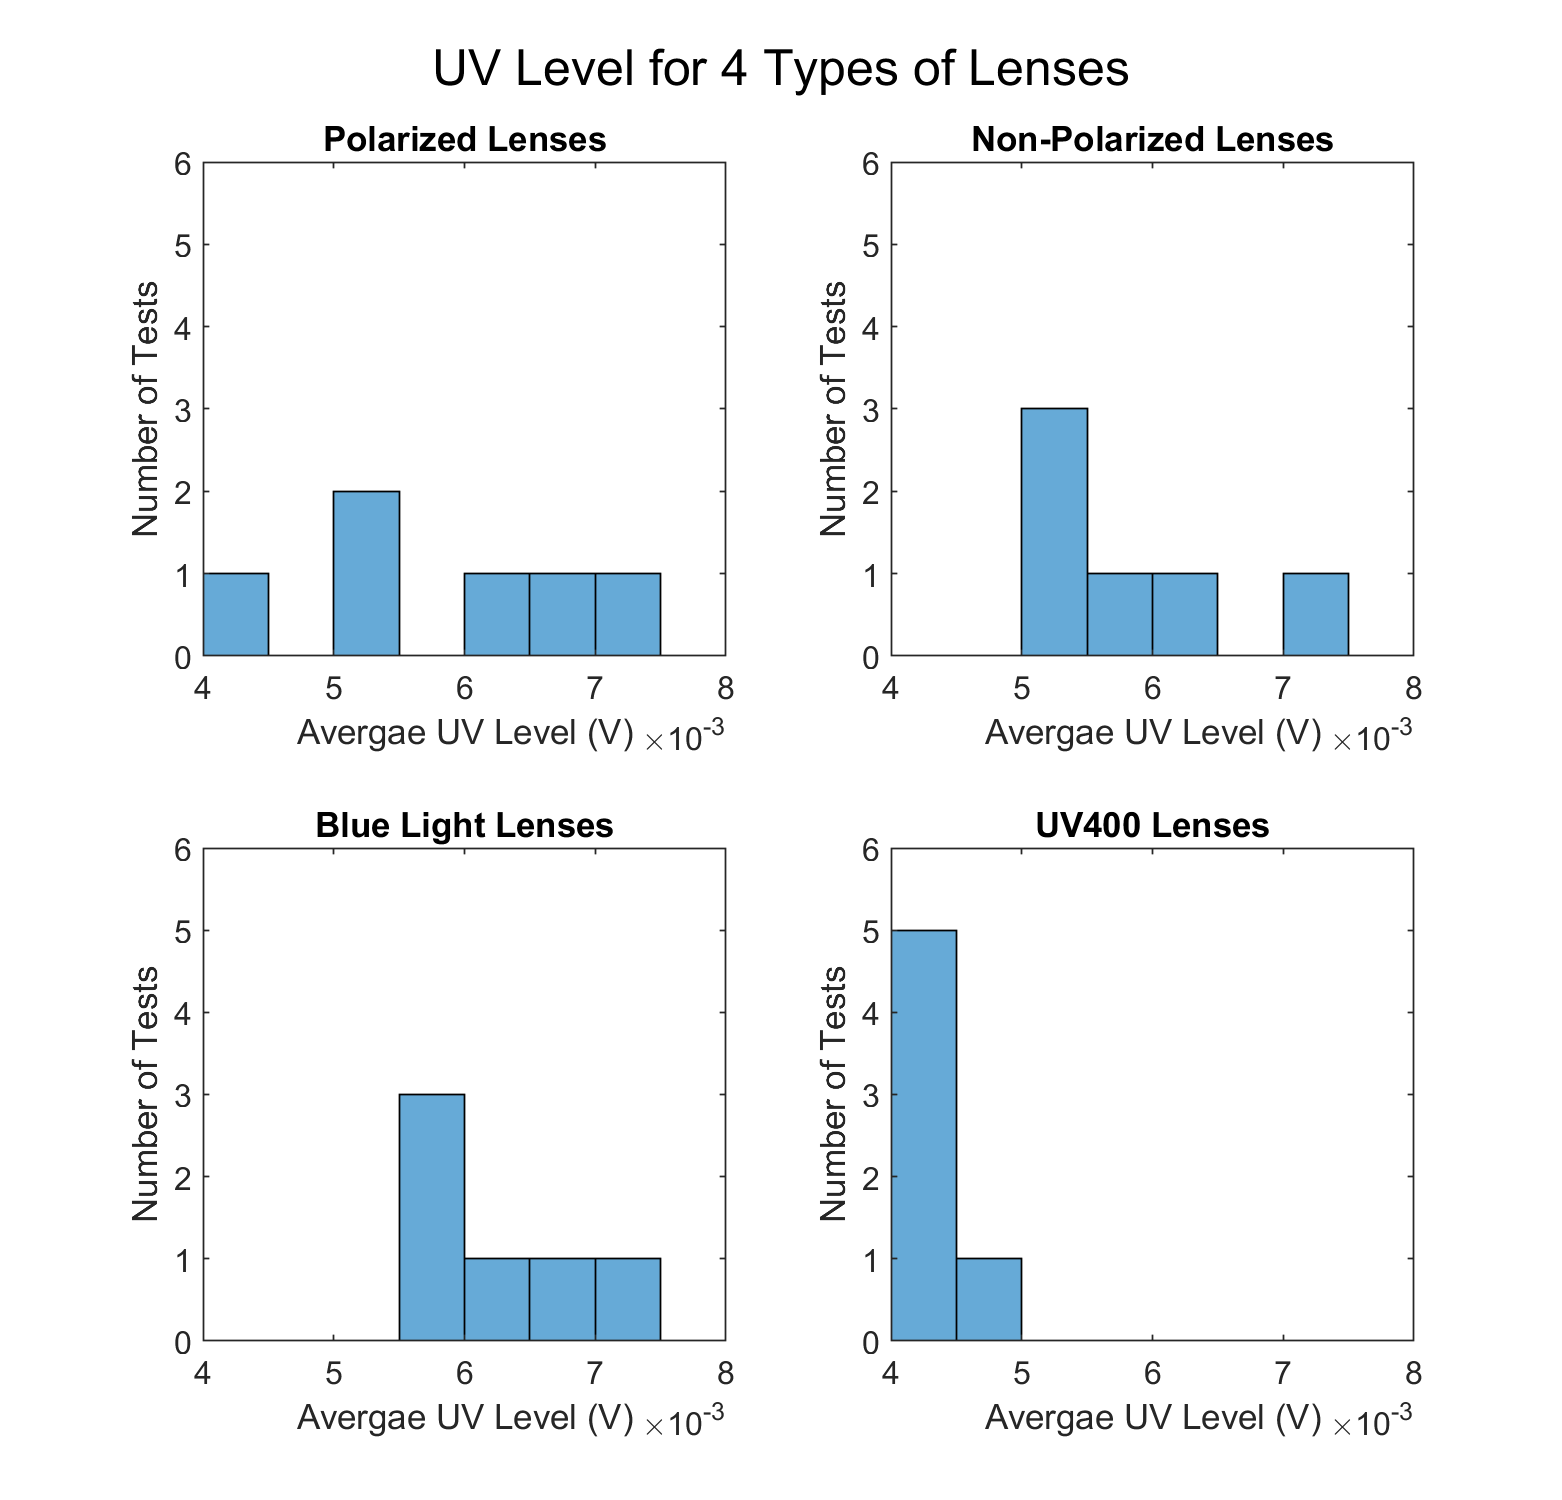

figure1 = figure('Position', [100, 100, 625, 600]);
subplot(2,2,1)
histogram(P,"BinWidth",5*10^-4) %Polarized
xlabel('Avergae UV Level (V)')
ylabel('Number of Tests')
title("Polarized Lenses")
axis([4*10^-3, 8*10^-3,0,6])

subplot(2,2,2)
histogram(NP,"BinWidth",5*10^-4) %Non-Polarized
xlabel('Avergae UV Level (V)')
ylabel('Number of Tests')
title("Non-Polarized Lenses")
axis([4*10^-3, 8*10^-3,0,6])

subplot(2,2,3)
histogram(BL,"BinWidth",5*10^-4) %Blue Light
xlabel('Avergae UV Level (V)')
ylabel('Number of Tests')
title("Blue Light Lenses")
axis([4*10^-3, 8*10^-3,0,6])

subplot(2,2,4)
histogram(MAX,"BinWidth",5*10^-4) %No Lens
xlabel('Avergae UV Level (V)')
ylabel('Number of Tests')
title("UV400 Lenses")
axis([4*10^-3, 8*10^-3,0,6])
sgtitle("UV Level for 4 Types of Lenses")

### Probability Density Functions

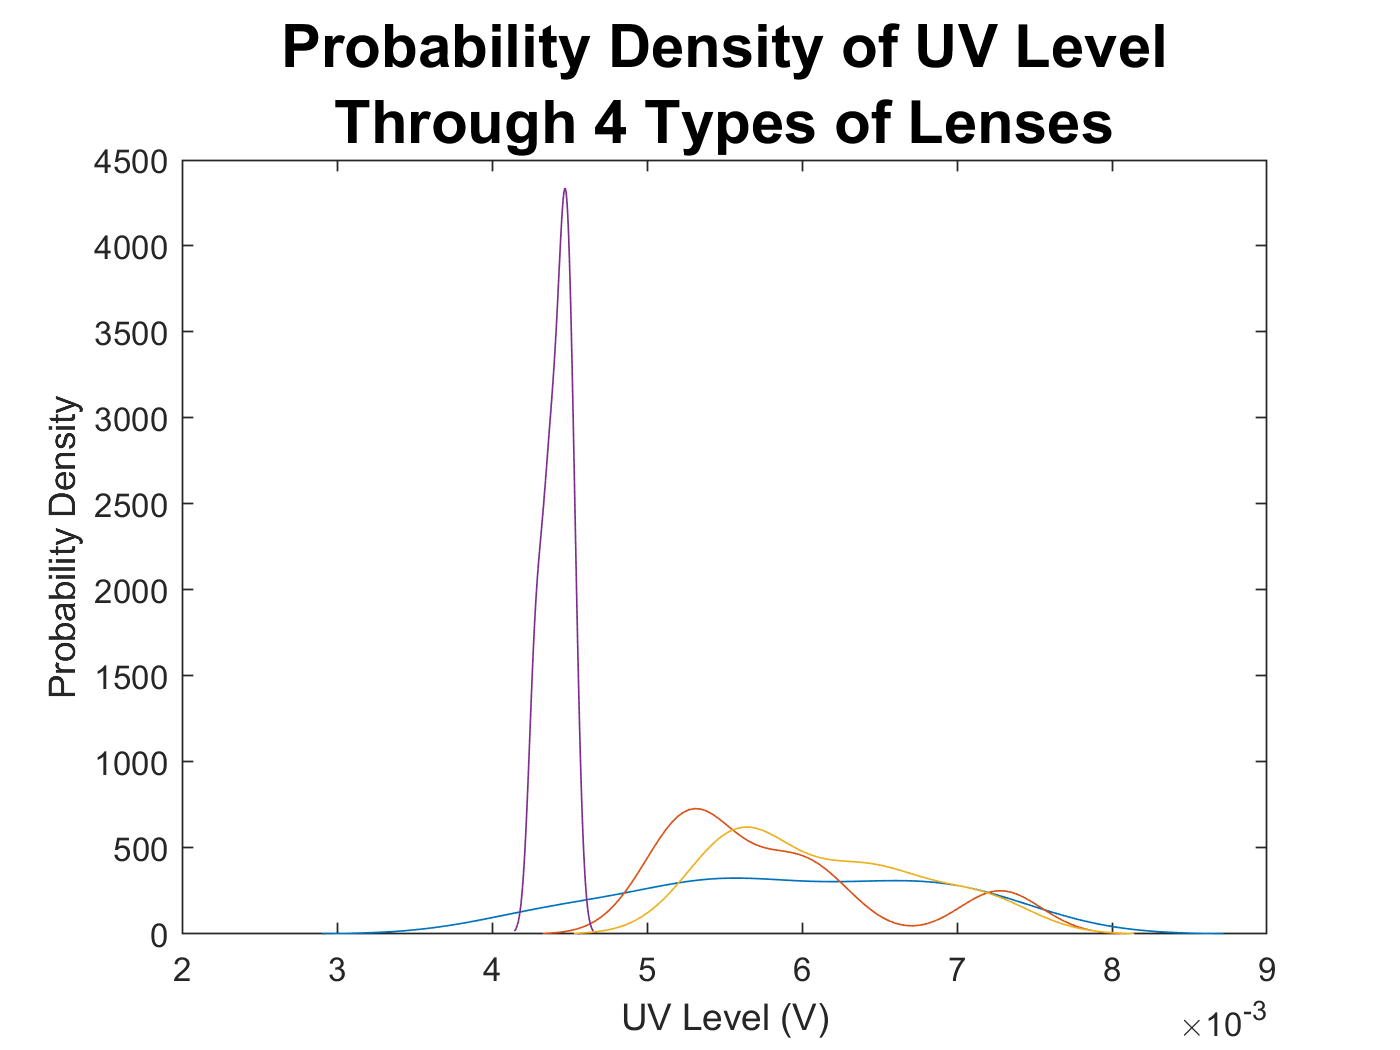

figure2 = figure;
ksdensity(P, "Bandwidth", 5.1326*10^-4); % Default Bandwidth = 7.6989e-04
hold on
ksdensity(NP, "Bandwidth", 2.6445*10^-4); % Default Bandwidth = 3.9667e-04
ksdensity(BL, "Bandwidth", 3.2647*10^-4); % Default Bandwidth = 4.8971e-04
ksdensity(MAX, "Bandwidth", 4.4893*10^-5); % Default Bandwidth = 6.7339e-05
hold off
%legend('Polarized','Non-Polarized','Blue Light', "UV400")
ylabel('Probability Density')
xlabel('UV Level (V)')
title(["\fontsize{18}Probability Density of UV Level"+newline+"Through 4 Types of Lenses"])
hold off

**Take Aways:**

From the histograms and probability density functions, it seems that while the Polarized, Non-Polarized, and Blue Light lenses all filter out approximately the same amount of UV light with similar variances from the mean, the UV400 lenses filter out the most UV and have very little variance.

### Box Plots

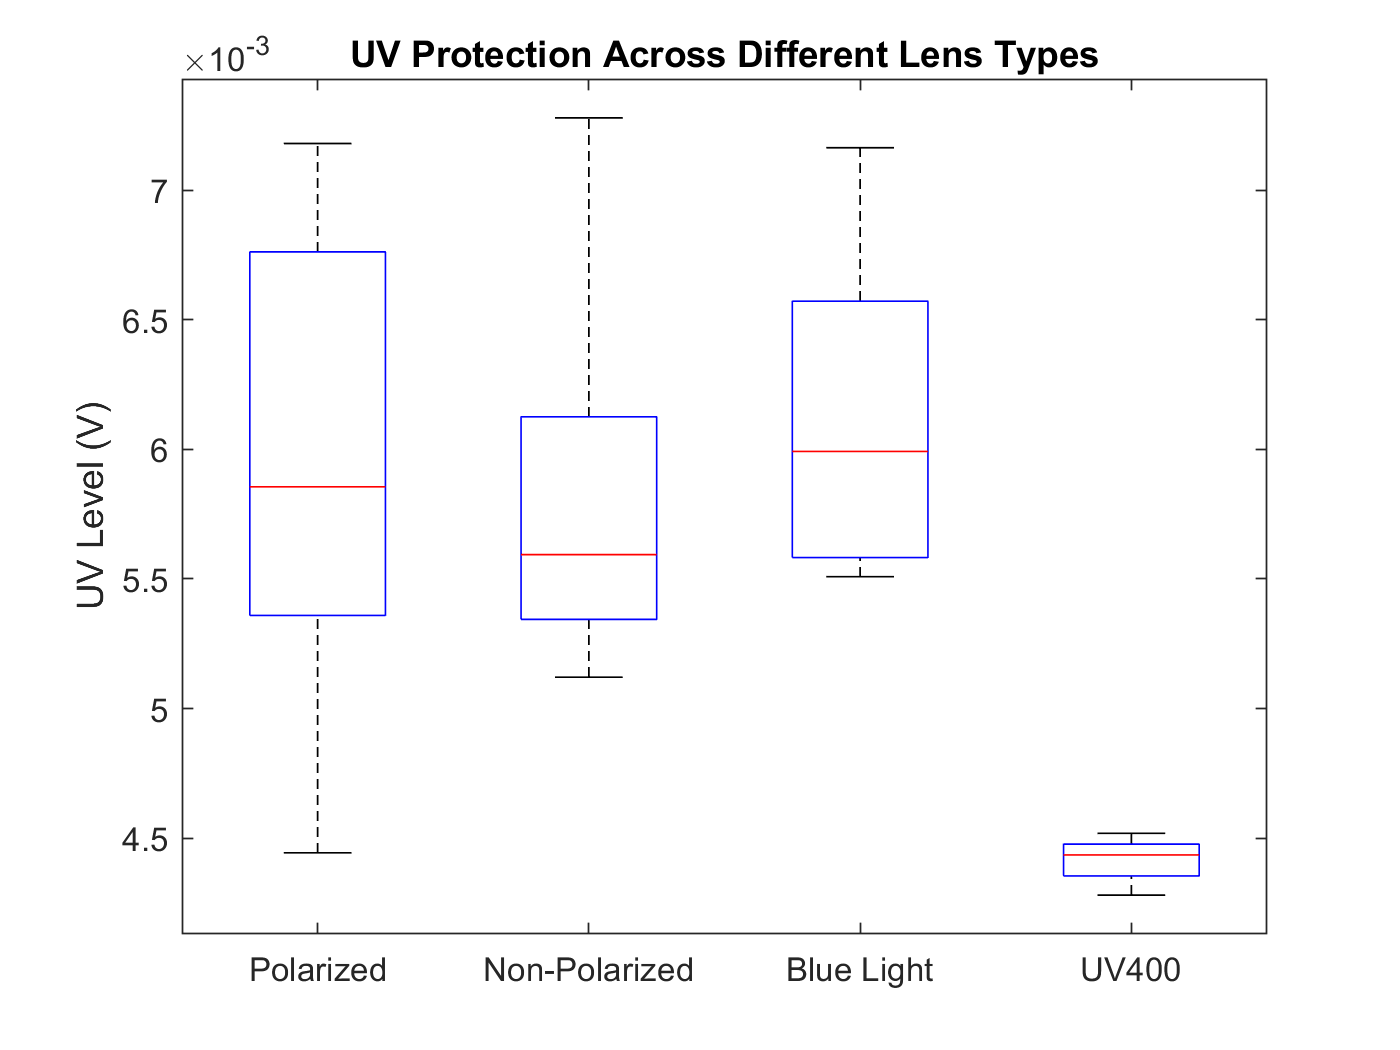

% Salaries Boxplot
figure3 = figure;
boxplot(LensDataLong,LensTypeLong,"Labels",{'Polarized','Non-Polarized','Blue Light','UV400'})
ylabel('UV Level (V)')
title('UV Protection Across Different Lens Types')

**Take Aways:**

Similar conclusions can be drawn from the boxplot as from the histograms and probability density functions. The UV400 lenses clearly have a much lower mean than all the other lenses. However, there may be significant difference in variance among some of the other lenses.

## DESCRIPTIVE STATISTICS - NUMERIC

All of the numeric descriptive statistics are univariate becuase it is simply the report of the independent variable of voltage from the UV sensor. There is no other variable being reported or that this vaiable relies on.

% Polarized Data Table
tabPolarized = table();
tabPolarized.Mean = mean(P)';
tabPolarized.Med = median(P)';
tabPolarized.SD = std(P)';
tabPolarized.IQR = iqr(P)';
tabPolarized.Min = min(P)';
tabPolarized.Max = max(P)';

% Non-Polarized Data Table
tabNonPolarized = table();
tabNonPolarized.Mean = mean(NP)';
tabNonPolarized.Med = median(NP)';
tabNonPolarized.SD = std(NP)';
tabNonPolarized.IQR = iqr(NP)';
tabNonPolarized.Min = min(NP)';
tabNonPolarized.Max = max(NP)';

% Blue Light Data Table
tabBlueLight = table();
tabBlueLight.Mean = mean(BL)';
tabBlueLight.Med = median(BL)';
tabBlueLight.SD = std(BL)';
tabBlueLight.IQR = iqr(BL)';
tabBlueLight.Min = min(BL)';
tabBlueLight.Max = max(BL)';

% UV400 Data Table
tabUV400 = table();
tabUV400.Mean = mean(MAX)';
tabUV400.Med = median(MAX)';
tabUV400.SD = std(MAX)';
tabUV400.IQR = iqr(MAX)';
tabUV400.Min = min(MAX)';
tabUV400.Max = max(MAX)';

% No Lense Data Table
tabNoLens = table();
tabNoLens.Mean = mean(NoL)';
tabNoLens.Med = median(NoL)';
tabNoLens.SD = std(NoL)';
tabNoLens.IQR = iqr(NoL)';
tabNoLens.Min = min(NoL)';
tabNoLens.Max = max(NoL)';

% Concatenate all tables into 1 decriptive statistics table and show concatenated table.
descrStats = vertcat(tabPolarized,tabNonPolarized,tabBlueLight,tabUV400, tabNoLens);
descrStats.Properties.RowNames = {'Polarized','Non-Polarized','Blue Light','UV400','No Lens'};
descrStats

descrStats = 5×6 table
                       Mean          Med           SD           IQR           Min          Max   
                     _________    _________    __________    __________    _________    _________

    Polarized        0.0059093    0.0058555     0.0010077     0.0014031    0.0044432    0.0071803
    Non-Polarized    0.0058428    0.0055938    0.00079418    0.00078161    0.0051207    0.0072791
    Blue Light       0.0061351    0.0059919    0.00065496    0.00098939    0.0055088    0.0071638
    UV400            0.0044165     0.004435    8.8405e-05    0.00012272    0.0042799    0.0045186
    No Lens             1.3354       1.2932       0.20243       0.28856       1.1153       1.6621


**Take Aways:**

The descriptive numerical statistics support the conclusions drawn from the visual statitics. The UV400 lenses have a lower mean, standard deviation, max, min, and inner quartile range than all other lenses. It is difficult to draw any hypotheses about differences between the other 3 lenses. The "No Lense" data is there to show how effective each lense is. See calculations for exact effectiveness calculations relative to the no lense data.

## INFERENTIAL STATISTICS

## TEST OF NORMALITY

For a four-sample, independent test, we need to test the normality of each group.

Underlying Assumptions of the Test :

- The data are continuous.

- The data are from a sample that was randomly drawn from a process/population.

Method: Anderson-Darling and Normality Plot

Step 1 : (Note that a non-directional test is assumed.)

H0 :$\gamma$_3 = 0 and $\gamma$_4 = 0 for all groups

H1 : $\gamma$_3 $\not=$ 0 and $\gamma$_4 $\not=$ 0 for some/all groups

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make

alpha1 = 0.05

alpha1 = 0.0500

Step 3 : We will use the AD test statistic.

Step 4 : We will use the AD RSD

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    Quantitative: Reject H0 if any p-value < $\alpha$ 

Step 6 : Calculations

### Normality Plots

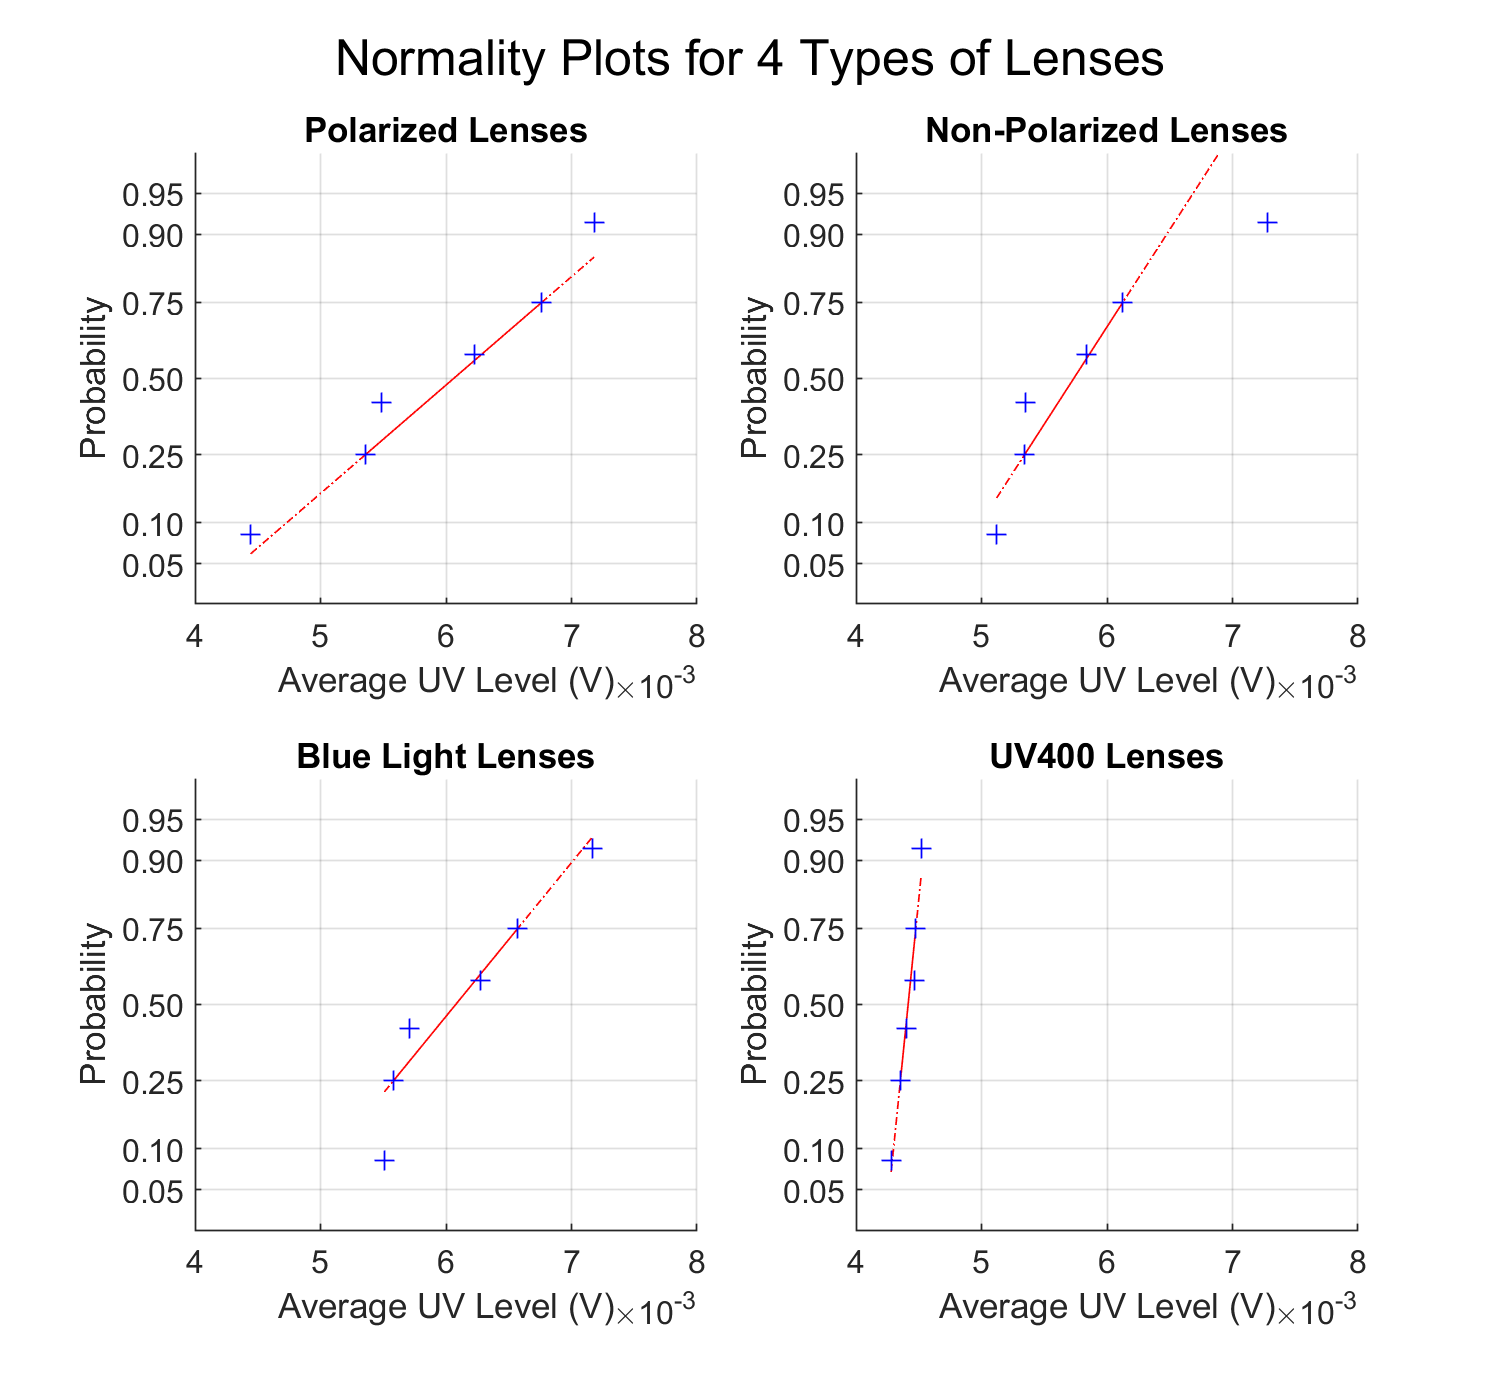

figure4 = figure('Position', [100, 100, 600, 550]);
subplot(2,2,1)
normplot(P) %Polarized
title('Polarized Lenses')
xlabel('Average UV Level (V)')
axis([4*10^-3, 8*10^-3,-2,2])

subplot(2,2,2)
normplot(NP) %Non-Polarized
title('Non-Polarized Lenses')
xlabel('Average UV Level (V)')
axis([4*10^-3, 8*10^-3,-2,2])

subplot(2,2,3)
normplot(BL) %Blue Light
title('Blue Light Lenses')
xlabel('Average UV Level (V)')
axis([4*10^-3, 8*10^-3,-2,2])

subplot(2,2,4)
normplot(MAX) %UV400 Lens
title('UV400 Lenses')
xlabel('Average UV Level (V)')
axis([4*10^-3, 8*10^-3,-2,2])
sgtitle("Normality Plots for 4 Types of Lenses")

**Take Aways:**

From these 4 normality plots, it seems that all 4 populations roughly follow their respective linear regression lines, indicating normality. Further testing using the Anderson-Darling statistic is necessary to confirm these hypotheses.

###  Anderson-Darling Statistic Calculations

[H_AD(1),p_AD(1),ADSTAT(1),CV(1)]=adtest(P, 'Alpha', 0.05); %Polarized
[H_AD(2),p_AD(2),ADSTAT(2),CV(2)]=adtest(NP, 'Alpha', 0.05); %NonPolarized
[H_AD(3),p_AD(3),ADSTAT(3),CV(3)]=adtest(BL, 'Alpha', 0.05); %Blue Light
[H_AD(4),p_AD(4),ADSTAT(4),CV(4)]=adtest(MAX, 'Alpha', 0.05); %UV400
H_AD

H_AD = 1×4 logical array
   0   0   0   0


p_AD

p_AD =     0.9094    0.2120    0.4527    0.8048


### Decision

Step 7a) Decision : **Fail to Reject H0** (for all 4 groups)

7b) p = see above

7c) We have sufficient statistical evidence to infer that the populations from which these data were randomly sampled are

symmetrical and mesokurtic, and, therefore, may be approximated by the Normal distribution. 

Based on n = 6 for all populations, the A-D tests are appropriate for this analysis.

**Take Aways:**

All 4 populations can be approximated by the normal distribution. The following infferential statistics will use this approximation.

## TEST OF VARIANCE

The test of variance will tell us what t-test to use in the test of location.

Underlying Assumptions of the Test :

- The data are continuous.

- The data are from a sample that was randomly drawn from a process/population.

- The data are normally distributed (all groups).

Method: For a four-sample, independent test:  Levene Test

Step 1 : (Note that a non-directional test is assumed.)

H0 : variance is equal for all groups

H1: variance is not equal across one or more groups

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make

    We will use the same alpha as that for the normality test

alpha1

alpha1 = 0.0500

Step 3 : We will use the Levene's Test Statistic (F Statistic)

Step 4 : We will use the RSD for F with (k - 1 = 4 - 1 = 3) and (n_total - k = 24 - 4 = 20) degrees of freedom.

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    We will reject the null if p < 0.05

Step 6: Calculations

### Levene test for Variance

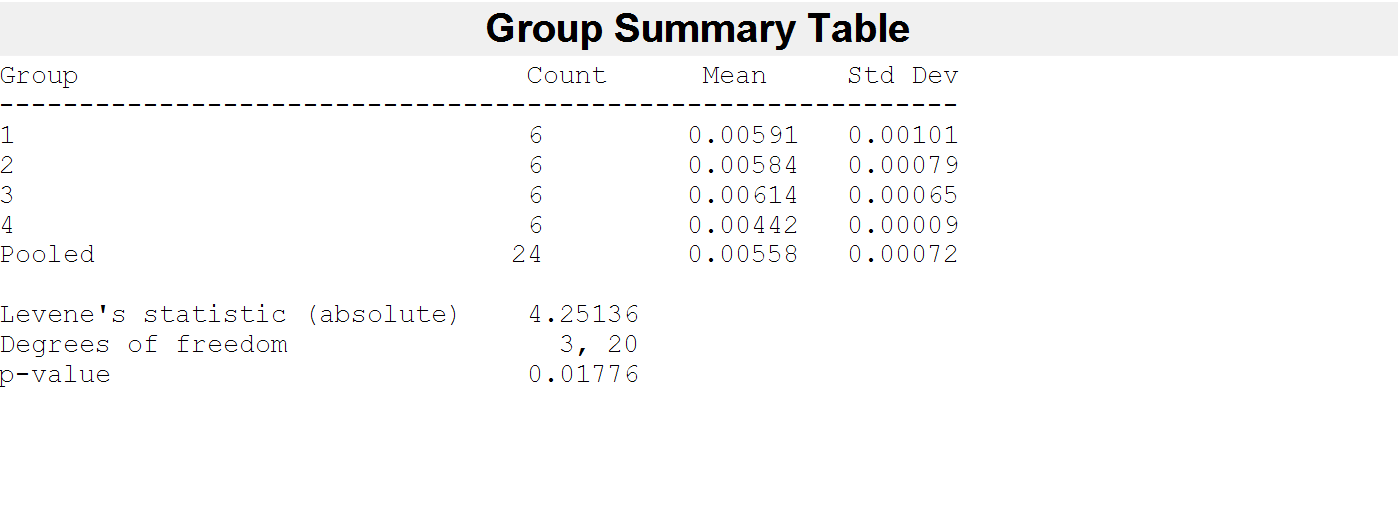

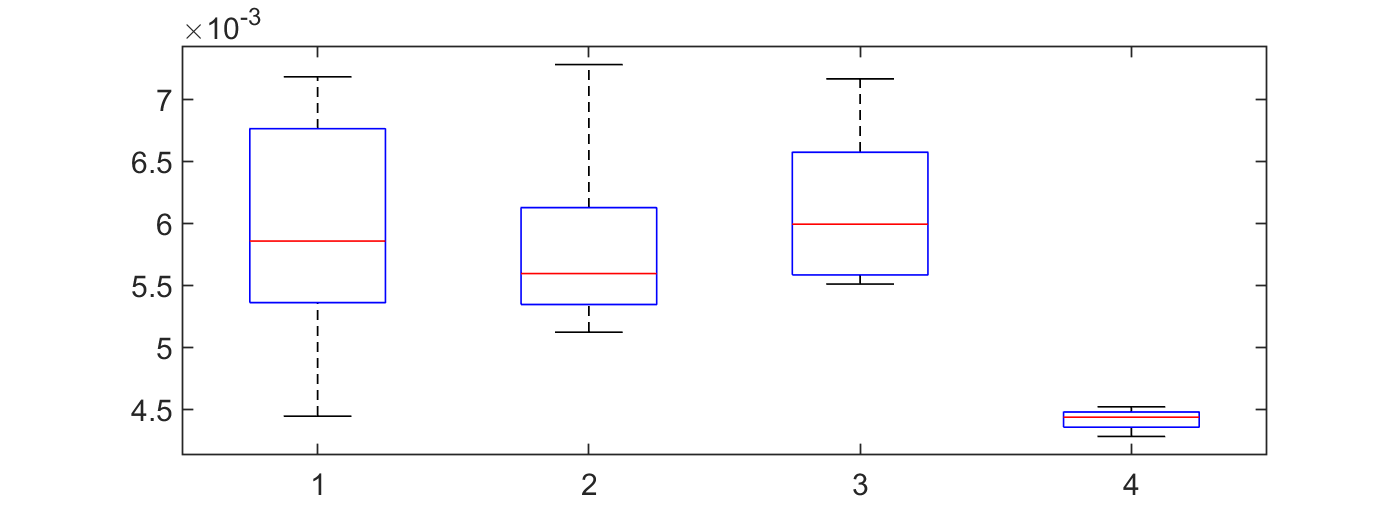

[p_var,STATS_var] = vartestn(LensDataLong,LensTypeLong,'TestType','LeveneAbsolute');

### Decision

Step 7a) Decision : ** Reject H0**

7b) p = 0.01776; Less than alpha (0.05)

7c) We have sufficient statistical evidence to infer that one or more of the variances of the populations from which these samples were drawn are not equal**.**

**Tale Aways:**

There is at least one population with a variance statistically different from at least one other population. Knowing that the variances are unequal will inform which test of loaction to use.

## Post-Hoc Analysis - Variance

We will use 6 pairwise Levene's tests using manual Bonferroni calculation analysis because we have a 4-sample population.

Underlying Assumptions of the Tests :

- The data are continuous.

- The data are from a sample that was randomly drawn from a process/population.

- The data are normally distributed (all groups).

Method: Six Individual Levene's Tests

Step 1 : (Note that non-directional tests are assumed.)

H0 : variance is equal for both groups

H1: variance is not equal between the two groups

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make

**    Bonferroni: **We divide the normal alpha of 0.05 by 6 to account for the 6 pariwise comparisons.

alpha1_PC = alpha1/6;

Step 3 : We will use the Levene's Test Statistic (F Statistic)

Step 4 : We will use the RSD for F with (k - 1 = 2 - 1 = 1) and (n_total - k = 12 - 1 = 11) degrees of freedom.

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    We will reject the null if p < 0.0083333 (aka. 0.05 / 6)

Step 6: Calculations

[h_PC(1), p_PC(1)] = vartest2(P,NP,'Alpha',alpha1_PC);   % P vs. NP
[h_PC(2), p_PC(2)] = vartest2(P,BL,'Alpha',alpha1_PC);   % P vs. BL
[h_PC(3), p_PC(3)] = vartest2(P,MAX,'Alpha',alpha1_PC);  % P vs. UV400
[h_PC(4), p_PC(4)] = vartest2(NP,BL,'Alpha',alpha1_PC);  % NP vs. BL
[h_PC(5), p_PC(5)] = vartest2(NP,MAX,'Alpha',alpha1_PC); % NP vs. UV400
[h_PC(6), p_PC(6)] = vartest2(BL,MAX,'Alpha',alpha1_PC); % BL vs. UV400
h_PC

h_PC =      0     0     1     0     1     1


p_PC

p_PC =     0.6139    0.3661    0.0001    0.6826    0.0002    0.0005


### Decision

Step 7a) Decision : ** Reject H0 for 3 of 6 pairwise comparisons**

7b) p = see above

7c) We have sufficient statistical evidence to infer that the UV400 lenses have a statistically different variance than all other lenses, and all other lenses have variances which are statistically identical.

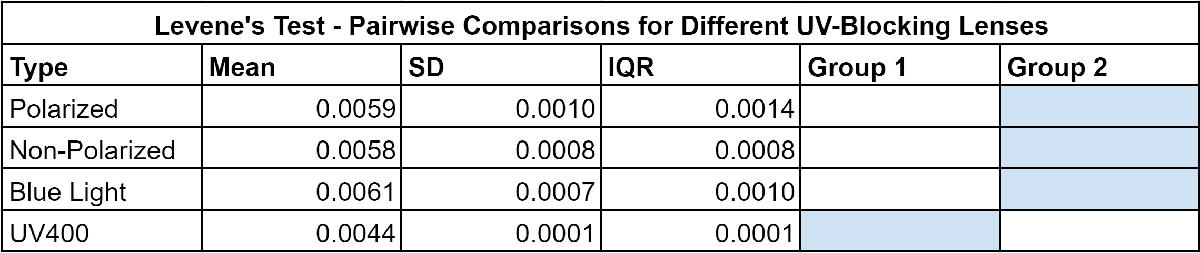

**Take Aways:**

From the 6 pairwise comparisons, we can see what was hypothesized was correct: the UV400 lenses have a smaller variance than all other lenses, and all the other lenses have the same variance. Next, location will be tested.

## TEST OF LOCATION

Underlying Assumptions of the Test :

- The data are continuous.

- The data are from a randomly-drawn sample from a process/population (independent specimens).

- Independent, Unequal Variance may be known or assumed.

Method: Welch ANOVA

Step 1 : (Note that a non-directional test is assumed.)

H0 : All means are equal 

H1: All means are not equal (at least two means are statistically different)

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make

    We will use the same alpha as that for the normality test

alpha1

alpha1 = 0.0500

Step 3 : We will use the F statistic.

Step 4 : We will use the RSD for F with 3 and 140 degrees of freedom.

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    We will reject the null if p < alpha

Step 6: Calculations    

[p_WANOVA,f_WANOVA,df1_WANOVA,df2_WANOVA] = wanova(LensDataLong,LensTypeLong)

p_WANOVA = 3.0074e-04

f_WANOVA = 20.5059

df1_WANOVA = 3

df2_WANOVA = 8.5380

The p-value is less than alpha. 

### Decision

Step 7a) Decision : **Reject H0**

7b) p < .001 (p less than alpha)

7c) We have sufficient statistical evidence to infer that the means of one or more of the populations from which these samples were drawn are unequal. (If equal: The difference between mu_1 and mu_2 is due to sampling error, and sampling error alone.)

7d) Appropriate Point Estimates (UV )

    *M_P = 0.0059  |  M_NP = 0.0058  |  M_BL = 0.0061* *|  M_UV400 = 0.0044*

7e) Appropriate Interval Estimates (see below)

7f) Effect Size (See Below)

FOR ANOVA: We will need to find which groups are different, if we reject the null.  We do that through post-hoc analysis.

## Post-Hoc Analysis - Location

We will use a Games-Howell post-hoc analysis because we have a 4-sample population with unequal variances.

[h_GH,p_GH,stats_GH]=games_howell(LensDataLong,LensTypeLong,alpha1)

h_GH =    NaN     0     0     0
     0   NaN     0     1
     0     0   NaN     1
     0     1     1   NaN


p_GH =        NaN    0.9993    0.9667    0.0553
    0.9993       NaN    0.8974    0.0277
    0.9667    0.8974       NaN    0.0079
    0.0553    0.0277    0.0079       NaN


stats_GH = struct with fields:
    gnames: [4×1 double]
        md: [4×4 double]
         q: [4×4 double]
        df: [4×4 double]


stats_GH.md

ans =        NaN    0.0001   -0.0002    0.0015
   -0.0001       NaN   -0.0003    0.0014
    0.0002    0.0003       NaN    0.0017
   -0.0015   -0.0014   -0.0017       NaN


stats_GH.q

ans =        NaN    0.1794   -0.6510    5.1117
   -0.1794       NaN   -0.9837    6.1831
    0.6510    0.9837       NaN    9.0080
   -5.1117   -6.1831   -9.0080       NaN


stats_GH.df

ans =        NaN    9.4819    8.5846    5.0770
    9.4819       NaN    9.6502    5.1239
    8.5846    9.6502       NaN    5.1821
    5.0770    5.1239    5.1821       NaN


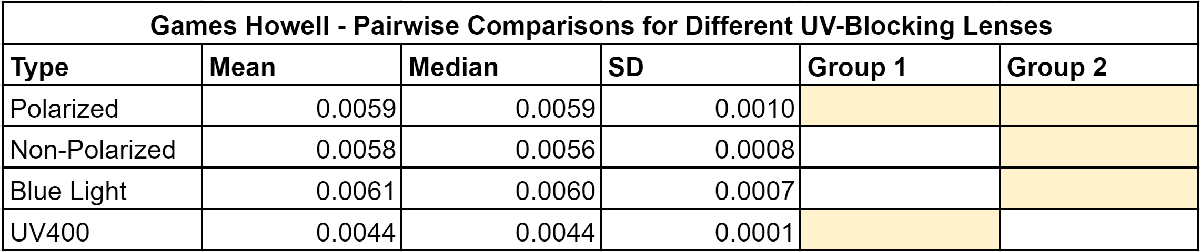

**Take Aways:**

From the Games-Howell post-hoc analysis, we learn that we have sufficient statistical evidence to infer that the UV400 lenses have a mean that is statistically different from that of the blue light lenses and the non-polarized lenses, but not different from that of the polarized lenses. There is also no difference between the means of the other lenses.

### Confidence Intervals

Since our data is normally distributed, we can find confidence intervals using normfit, which uses the t-value.

[MUHAT1,SIGMAHAT1,MUCI1,SIGMACI1] = normfit(P,alpha1) % Polarized CI

MUHAT1 = 0.0059

SIGMAHAT1 = 0.0010

MUCI1 =     0.0049
    0.0070


SIGMACI1 =     0.0006
    0.0025


[MUHAT2,SIGMAHAT2,MUCI2,SIGMACI2] = normfit(NP,alpha1) % Non-Polarized CI

MUHAT2 = 0.0058

SIGMAHAT2 = 7.9418e-04

MUCI2 =     0.0050
    0.0067


SIGMACI2 =     0.0005
    0.0019


[MUHAT3,SIGMAHAT3,MUCI3,SIGMACI3] = normfit(BL,alpha1) % Blue Light CI

MUHAT3 = 0.0061

SIGMAHAT3 = 6.5496e-04

MUCI3 =     0.0054
    0.0068


SIGMACI3 =     0.0004
    0.0016


[MUHAT4,SIGMAHAT4,MUCI4,SIGMACI4] = normfit(MAX,alpha1) % UV400 CI

MUHAT4 = 0.0044

SIGMAHAT4 = 8.8405e-05

MUCI4 =     0.0043
    0.0045


SIGMACI4 = 	1.0e+-3 *

    0.0552
    0.2168


**Take Aways:**

The confidence intervals of the means are as follows:

    Polarized:         Where x̄ = 0.0059, 95% CI [0.0049, 0.0070].

    Non-Polarized: Where x̄ = 0.0058, 95% CI [0.0050, 0.0067].

    Blue Light:        Where x̄ = 0.0061, 95% CI [0.0054, 0.0068].

    UV400:             Where x̄ = 0.0044, 95% CI [0.0043, 0.0045].

### Effect Size

[STATS_MES, varargout_mes] = mes1way(LensDataLong,{'omega2'},'group',LensTypeLong);

summaryTable = 4×9 cell array
    {'source'        }    {'SS'        }    {'df'}    {'MS'        }    {'F'       }    {'p'       }    {'omega2'  }    {'ci_lo'   }    {'ci_up'   }
    {'between-groups'}    {[1.1036e-05]}    {[ 3]}    {[3.6785e-06]}    {[  7.0638]}    {[  0.0020]}    {[  0.4312]}    {[ -0.0185]}    {[  0.5983]}
    {'within-groups' }    {[1.0415e-05]}    {[20]}    {[5.2076e-07]}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {'total'         }    {[2.1451e-05]}    {[23]}    {[9.3265e-07]}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


## Percentage UV Light Blocked Calculations

percentP = 100 - ((mean(P)/mean(NoL))*100);
percentNP = 100 - ((mean(NP)/mean(NoL))*100);
percentBL = 100 - ((mean(BL)/mean(NoL))*100);
percentMAX = 100 - ((mean(MAX)/mean(NoL))*100);

**Take Aways:**

Polarized lenses blocked approximately **99.56% **of UV light.

Non-Polarized lenses blocked approximately **99.56% **of UV light.

Blue Light lenses blocked approximately **99.54% **of UV light.

UV400 lenses blocked approximately **99.67% **of UV light.

## CONCLUSION

We learned quite a few different things about our samples. First, from the Anderson-Darling Test we learned that all 4 populations can be assumed to be normally distributed. Second, we learned from the Levene's test, that one or more of the variances of the groups was statistically different from the rest. Third, we learned from the 6 pairwise Levene's tests that the UV400 lenses have a statistically lower variance than all other lenses, and all other lenses have identical variance. Fourth, we learned from the Welch's ANOVA that one or more of our populations have a mean that is statistically different from the rest. Fifth, we learned from our Games-Howell Test in our Post-Hoc Analysis there is no statistical difference of the means for the following groups of lenses: [Polarized, UV400] and [Polarized, Non-Polarized, Blue Light]. This means the following comparisons can be drawn about the means of the lense types: [UV400 < Non-Polarized], [UV400 < Blue Light]. Finally, we learned from our omega squared values that 43% of the overall variance comes from the difference in the means between the groups.

Ultimately, if you are looking for a pair of glasses to protect their eye from the harmful effects of UV light, UV400 lenses will be better in both protection and reliability than both non-polarized and blue light glasses, and whiile not sttaistically more effective than polarized glasses, will also be more reliable than polarized glasses. This confirms our hypothesis that UV400 glasses are the best glasses to purchase to protect your eyes from UV light.